# Applying Ocean Color Algorithms

Description: This script loops through a directory with Landsat 8 images and applies the Quasi-Analytical Algorithm (version 6) from Lee et al. 2002, diffuse attenuation coefficient algorithm from Lee et al. 2004, Landsat 8 Secchi disk depth algorithm from Lee et al. 2016, and SAVE model from Wei et al. (2018). 

% Set Up
clear
clc
close all 

% Change to virginiaCoast Folder
cd '/Users/kellyluis/PycharmProjects/oceanoptics/Matlab/Examples/virginiaCoast/' % Change for your system

% Add Functions to Path 
addpath('/Users/kellyluis/PycharmProjects/oceanoptics/Matlab/Examples/virginiaCoast/functions') % Change for your system

% Loop Through Directory and Write Coordinates to a Structure
sdir = dir('/Users/kellyluis/PycharmProjects/oceanoptics/Matlab/Examples/virginiaCoast/datasets/*OC');
spath = '/Users/kellyluis/PycharmProjects/oceanoptics/Matlab/Examples/virginiaCoast/datasets/';

% Specify Variables and Coordinates of Interest
vi = {'Lat','Lon','kd_490','chl','rrs_443','rrs_482','rrs_561','rrs_655','l2_flags'};
site_names = {'Site 6','Site 12', 'Site 17'};
coord = [37.36764 -75.73592; 37.4670924 -75.668335; 37.29038 -75.784927];

% Specify Wavelength
wl = [443 482 561 655];

% Loop Through Images
for file = 1:length(sdir)
    
    cd(spath)
    
    % Read Files
    filename = sdir(file).name;
    L8_raw = readL2(filename);
    
    % Write Datetime Information to Structure
    L8coord.date(file) = L8_raw.date;
    
    % Write Variables of Interest 
    for param = 1:length(vi)
        L8coord.(vi{param})(:,:,file) = extractC(L8_raw.(vi{param}), L8_raw.Lat, L8_raw.Lon, coord);
    end
    
end

## Apply Quasi Analytical Algorithm (v6) to Derive Inherent Optical Properties

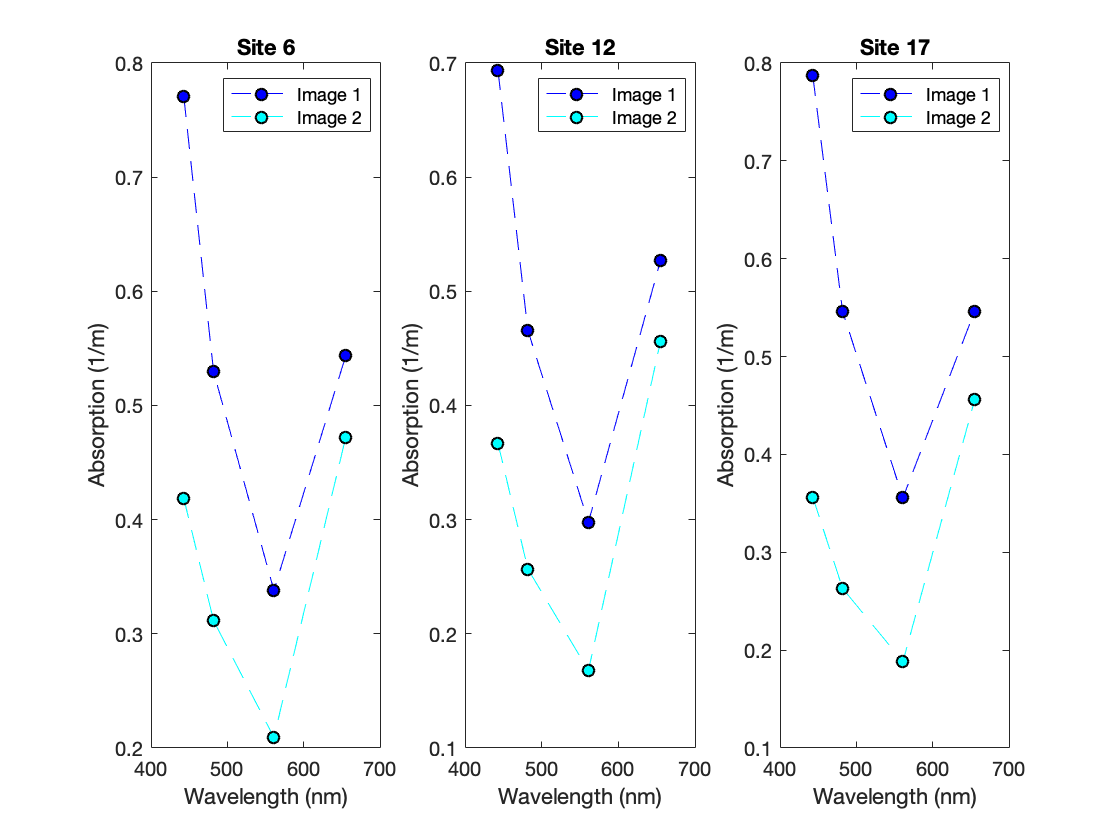

for image = 1:size(L8coord.rrs_443,3)
    for site = 1:size(L8coord.rrs_443,2)
        for meas = 1:size(L8coord.rrs_443,1)
        
        % Set Rrs Values
        Rrs = [L8coord.rrs_443(meas,site,image) L8coord.rrs_482(meas,site,image) L8coord.rrs_561(meas,site,image) L8coord.rrs_655(meas,site,image)];
        
        % Apply QAA
        [a(meas,:,site,image), bb(meas,:,site,image), apg(meas,:,site,image), bbp(meas,:,site,image), ~] = qaa_v6_l8(Rrs, wl);
        end
    end
end

% Quick Visualization for Absorption
a_demo = squeeze(nanmean(a,1));
colors = jet(size(a_demo,3));

% Plot Absorption Spectra
figure(1)
for pl = 1:size(a_demo,2)
    subplot(1,3,pl)
    for image = 1:size(a_demo,3)
        plot(wl, a_demo(:,pl,image),'o--','color',colors(image,:), 'MarkerFaceColor',colors(image,:),'MarkerEdgeColor','k')
        xlabel('Wavelength (nm)')
        ylabel('Absorption (1/m)')
        hold on
    end
    legend({'Image 1', 'Image 2'})
    title(site_names{pl})
end

## Applying iop2kd function for derive Kd from IOPs

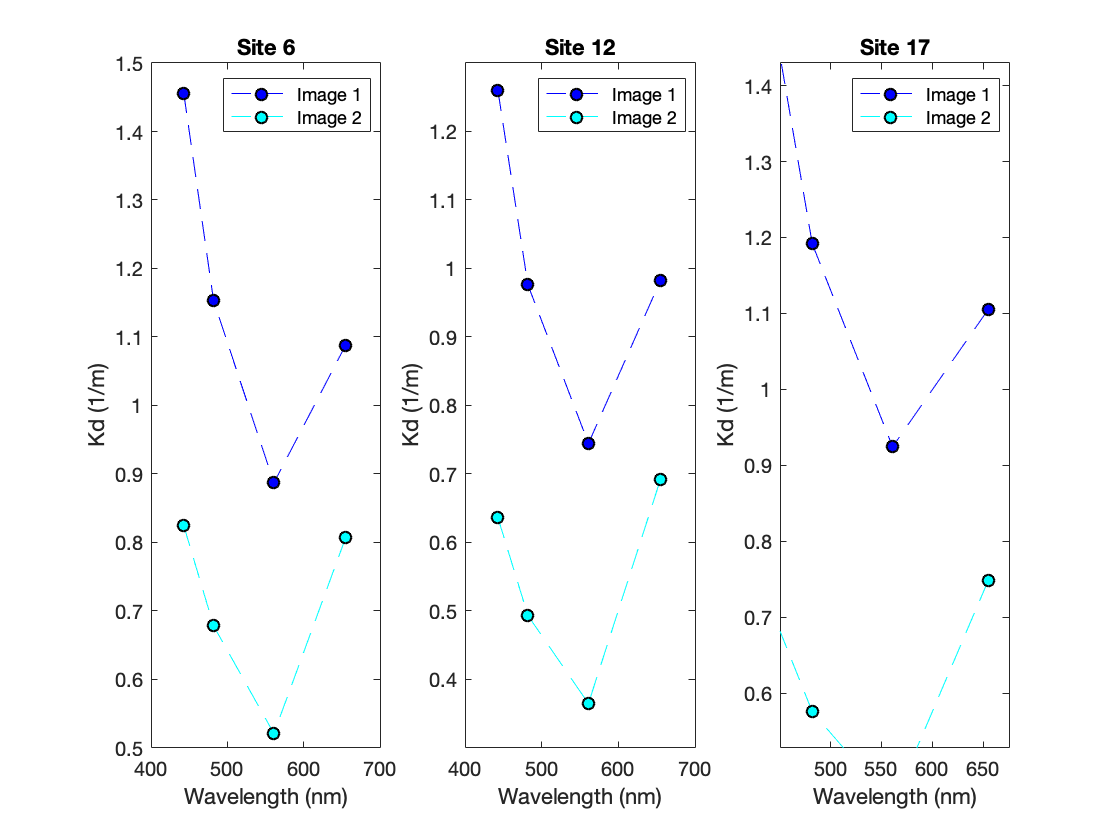

% Specify Inputs
bbw = [0.002 0.0014 0.0008 0.004];
sa = 30;

% Loop Through Matrices
for image = 1:size(a,4)
    for site = 1:size(a,3)
        for meas = 1:size(a,1)
            kd(meas,:,site,image) =iop2kd(a(meas,:,site,image),bb(meas,:,site,image),bbw,sa);
        end
    end
end 

% Quick Visualization
kd_demo = squeeze(nanmean(kd,1));

figure(2)
for pl = 1:size(kd_demo,2)
    subplot(1,3,pl)
    for image = 1:size(kd_demo,3)
        plot(wl, kd_demo(:,pl,image),'o--','color',colors(image,:), 'MarkerFaceColor',colors(image,:),'MarkerEdgeColor','k')
        xlabel('Wavelength (nm)')
        ylabel('Kd (1/m)')
        hold on
    end
    legend({'Image 1', 'Image 2'})
    title(site_names{pl})
end

## Applying Lee et al. (2016) Secchi Algorithm

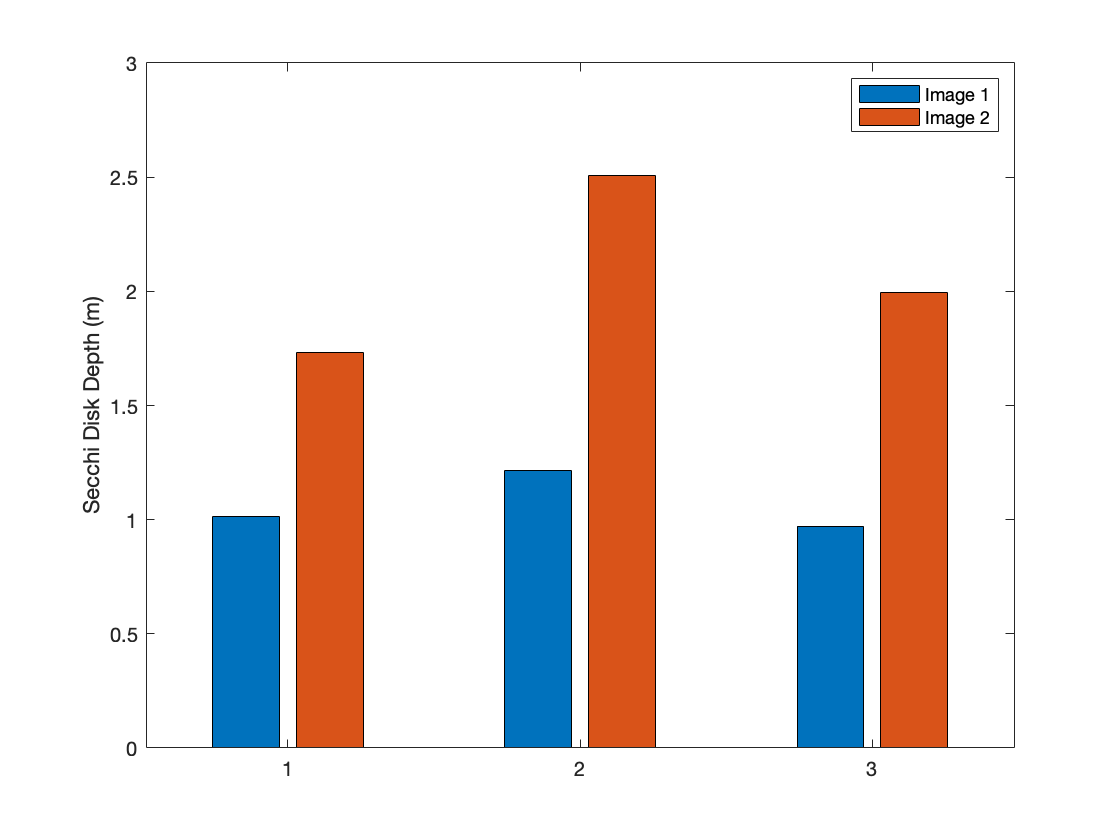

for image = 1:size(L8coord.rrs_443,3)
    for site = 1:size(L8coord.rrs_443,2)
        for meas = 1:size(L8coord.rrs_443,1)
        
        % Set Rrs Values
        Rrs = [L8coord.rrs_443(meas,site,image) L8coord.rrs_482(meas,site,image) L8coord.rrs_561(meas,site,image) L8coord.rrs_655(meas,site,image)];
        
        % Set Kd Values
        Kd = kd(meas,:,site,image);
        
        % Apply secchi_L8 funtion
        [Kdminwl(meas,site,image), Secchi(meas,site,image), Kdmin(meas,site,image)] = secchi_L8(Rrs, Kd, wl);
        
        end
    end
end

% Quick Visualization
secchi_demo = squeeze(nanmean(Secchi,1));

figure(3)
bar(secchi_demo)
ylabel('Secchi Disk Depth (m)')
legend({'Image 1', 'Image 2'})

## Apply Wei et al. (2018) SAVE Model 

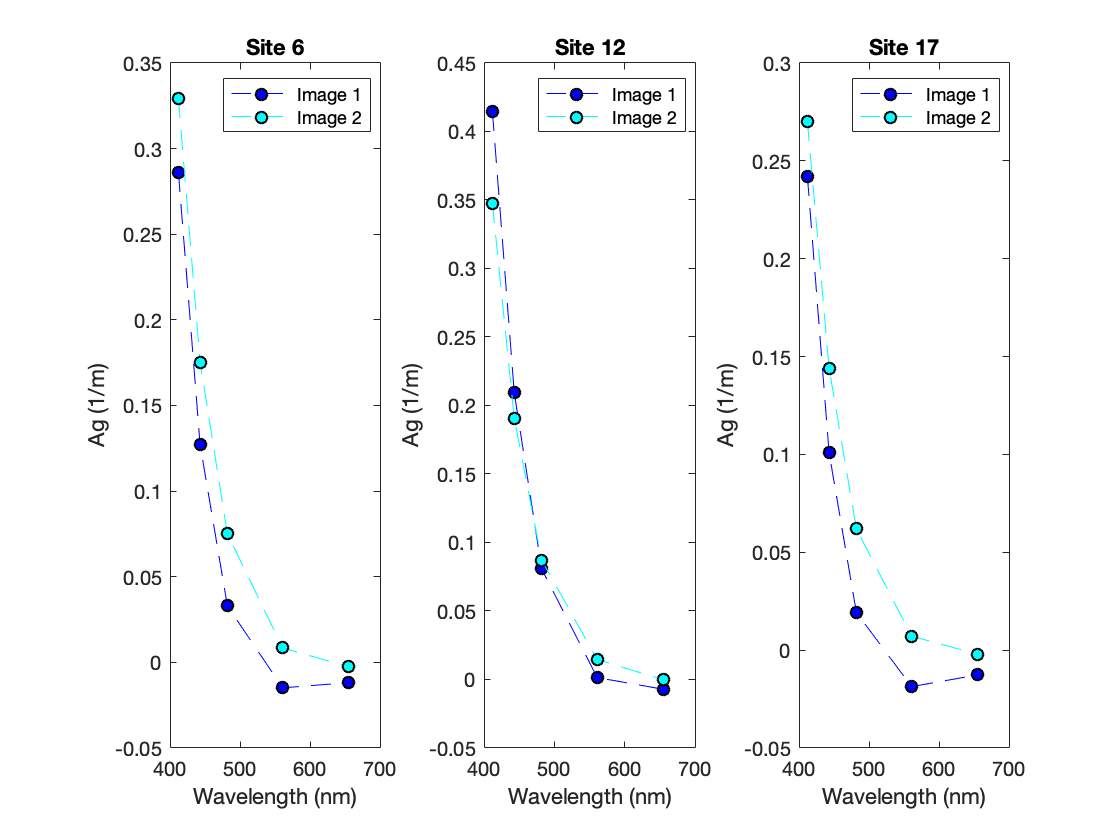

for image = 1:size(L8coord.rrs_443,3)
    for site = 1:size(L8coord.rrs_443,2)
        for meas = 1:size(L8coord.rrs_443,1)
        
        % Set Rrs Values
        Rrs = [L8coord.rrs_443(meas,site,image) L8coord.rrs_482(meas,site,image) L8coord.rrs_561(meas,site,image) L8coord.rrs_655(meas,site,image)];
        
        % Apply SAVE model
        [Rrs412(meas,:,site,image), aph(meas,:,site,image), adg(meas,:,site,image), ad(meas,:,site,image), ag(meas,:,site,image)] = save_model(Rrs, wl);
        
        end
    end
end

% Quick Visualization
wln = [412 wl];
ag_demo = squeeze(nanmean(ag,1));
ad_demo = squeeze(nanmean(ad,1));
adg_demo = squeeze(nanmean(adg,1));
aph_demo = squeeze(nanmean(aph,1));

figure(4)
for pl = 1:size(ag_demo,2)
    subplot(1,3,pl)
    for image = 1:size(ag_demo,3)
        plot(wln, ag_demo(:,pl,image),'o--','color',colors(image,:), 'MarkerFaceColor',colors(image,:),'MarkerEdgeColor','k')
        xlabel('Wavelength (nm)')
        ylabel('Ag (1/m)')
        hold on
    end
    legend({'Image 1', 'Image 2'})
    title(site_names{pl})
end

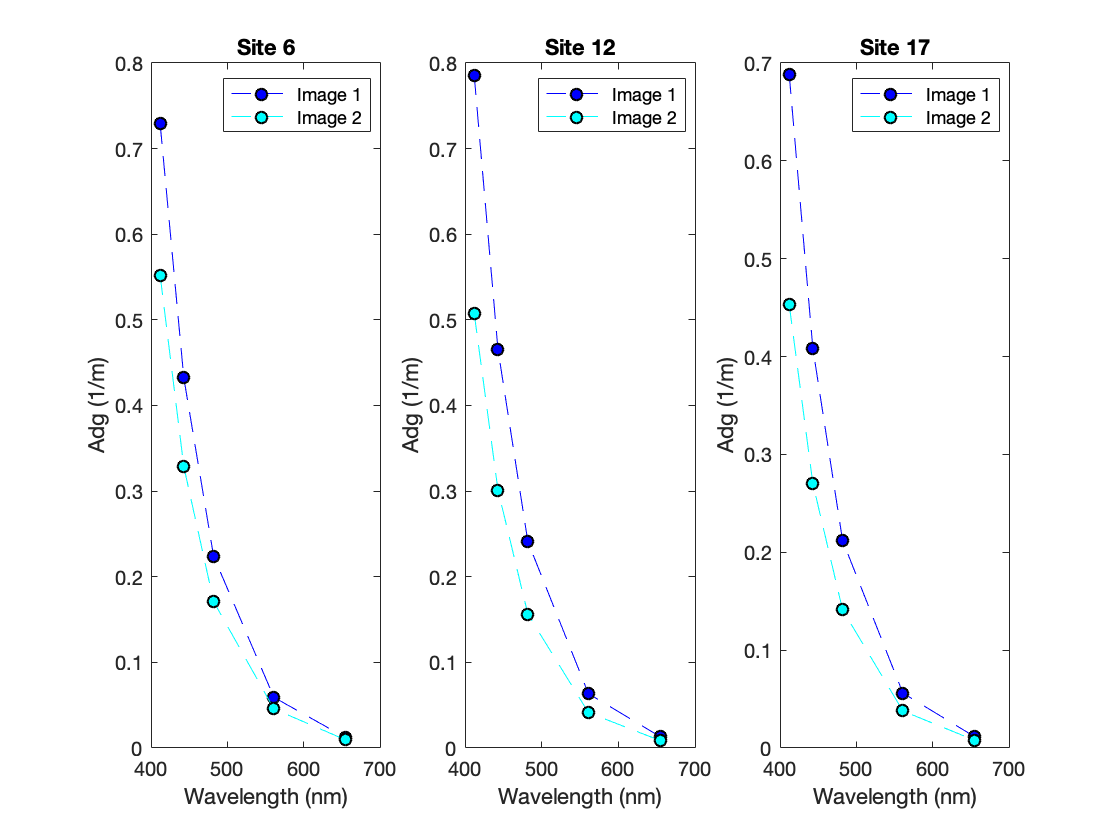

figure(5)
for pl = 1:size(ag_demo,2)
    subplot(1,3,pl)
    for image = 1:size(adg_demo,3)
        plot(wln, adg_demo(:,pl,image),'o--','color',colors(image,:), 'MarkerFaceColor',colors(image,:),'MarkerEdgeColor','k')
        xlabel('Wavelength (nm)')
        ylabel('Adg (1/m)')
        hold on
    end
    legend({'Image 1', 'Image 2'})
    title(site_names{pl})
end

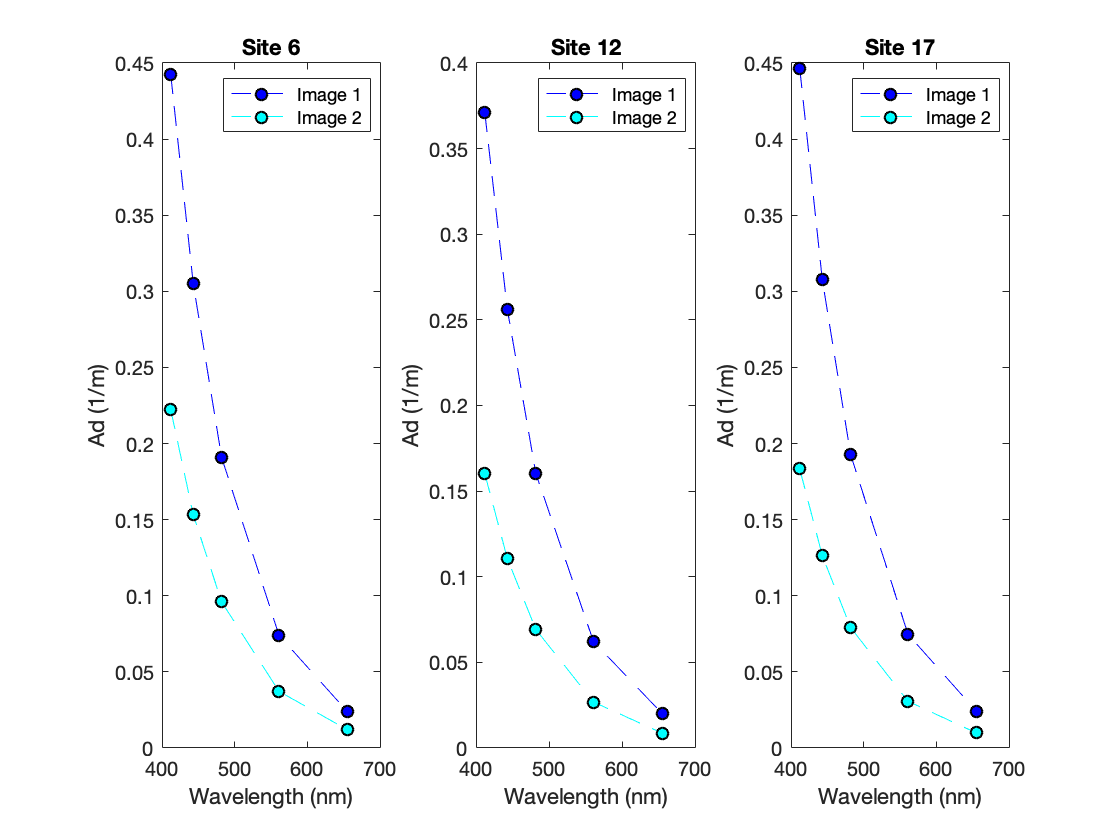

figure(6)
for pl = 1:size(ad_demo,2)
    subplot(1,3,pl)
    for image = 1:size(ad_demo,3)
        plot(wln, ad_demo(:,pl,image),'o--','color',colors(image,:), 'MarkerFaceColor',colors(image,:),'MarkerEdgeColor','k')
        xlabel('Wavelength (nm)')
        ylabel('Ad (1/m)')
        hold on
    end
    legend({'Image 1', 'Image 2'})
    title(site_names{pl})
end

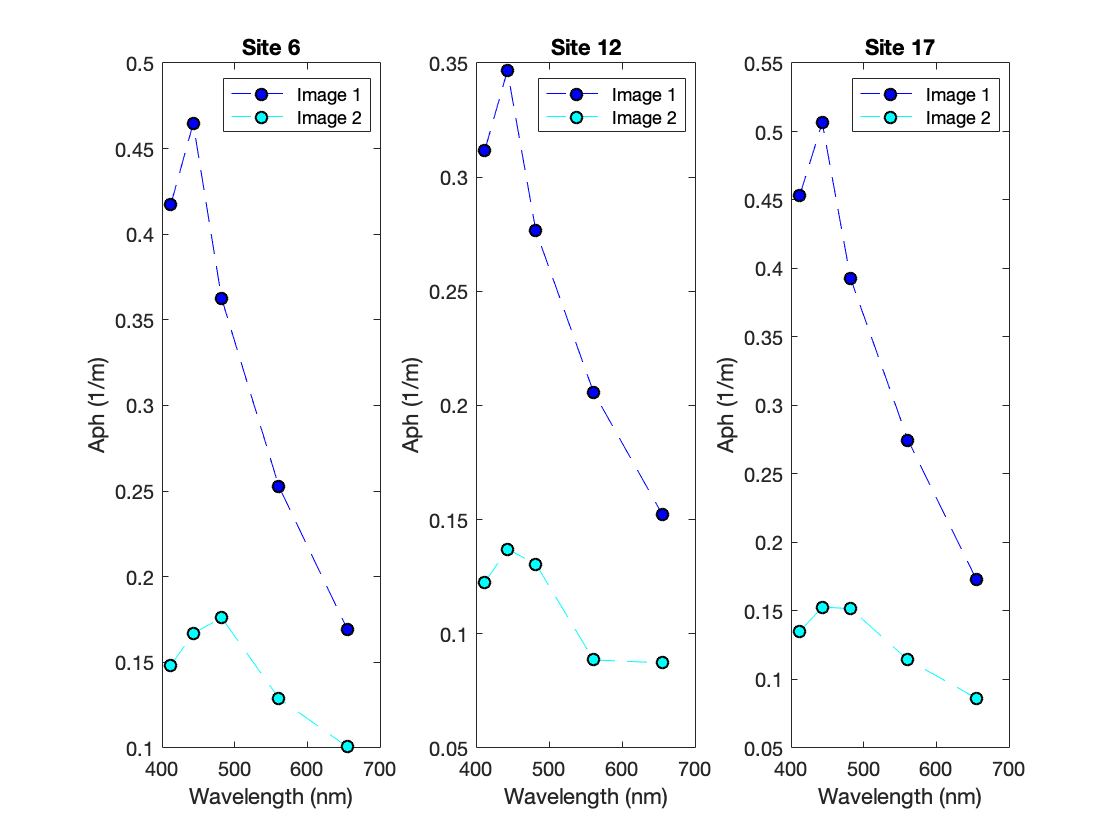

figure(7)
for pl = 1:size(aph_demo,2)
    subplot(1,3,pl)
    for image = 1:size(aph_demo,3)
        plot(wln, aph_demo(:,pl,image),'o--','color',colors(image,:), 'MarkerFaceColor',colors(image,:),'MarkerEdgeColor','k')
        xlabel('Wavelength (nm)')
        ylabel('Aph (1/m)')
        hold on
    end
    legend({'Image 1', 'Image 2'})
    title(site_names{pl})
end